# INVASIVE MODAL CONTROL (SELF TUNING)

a_model_setup

% Time and sampling
Ts = 1/1000;
num_periods = 100;
T_total = ceil((num_periods*2*pi/model.omega)/Ts)*Ts; % used to ensure at least num_periods are simulated
t_vec = 0:Ts:T_total;
t_num = length(t_vec);

% Initial state: [eta1, eta2, eta_dot1, eta_dot2, I, psi]
x0 = zeros(5,1);

% Store history
t_all = t_vec';
x_all = zeros(t_num, 5);
v_all = zeros(t_num, 1);
a_all = zeros(t_num, 2);
eta_e1_prev = 0;


% Control gains
model.k1 = 1.13;
model.k2 = 0.0002;
model.Ts = Ts;
psi = 0.05;
psi_lim = 0.3;

% Desired trajectory
A_target = 2e-3;                 % target amplitude (m)
omega = model.omega;             % target frequency (rad/s)
model.eta_star = @(t) A_target.*sin(omega.*t);
model.eta_ddot_star = @(t) -(A_target*omega^2).*sin(omega.*t);

% for n = 1:50
    % simulate itteration:
    for k = 1:length(t_vec)-1
        tk = t_all(k);
        tkp1 = t_all(k+1);
        tspan = [tk, tkp1];
        
        % control force:
        dx = f_beam_shaker_model(tk, x_all(k, :)', model);
        ei = dx(3) - model.eta_ddot_star(tk)*model.k1; % gain shaping

    
        % update psi
        if psi >= psi_lim
            psi = psi_lim;
        else
            psi_dot = model.k2 * ei^2;
            psi = psi + psi_dot * Ts;  % Euler integration
        end
        psi = min(psi, psi_lim);
        a_all(k, 1) = psi;
    
        control_volt = psi * ei;
        v_all(k) = control_volt;
        model.u_fun = @(t) control_volt;
    
        % simulate between samples
        [t_seg, x_seg] = ode45(@(t,x) f_beam_shaker_model(t, x, model), tspan, x0);
    
        x0 = x_seg(end,:)';
        x_all(k+1, :) = x0';
    end
    
    % % extract amplitude
    [t_lin, x_lin] = f_get_last_n_periods(t_all, x_all(:, 1), 5);
    [A_vec,B_vec] = f_get_fft_components(t_lin, x_lin, model.omega, model.harmonics);
    amplitude = sqrt(sum(A_vec.^2 + B_vec.^2))

amplitude = 0.0019

    % % % adjust gain shaping
    % amp_err = A_target/amplitude
    % if abs(amp_err-1) < 0.01
    %     "within tolerance"
    %     break
    % else
    %     model.k1 = model.k1 * amp_err;
    % end
% end


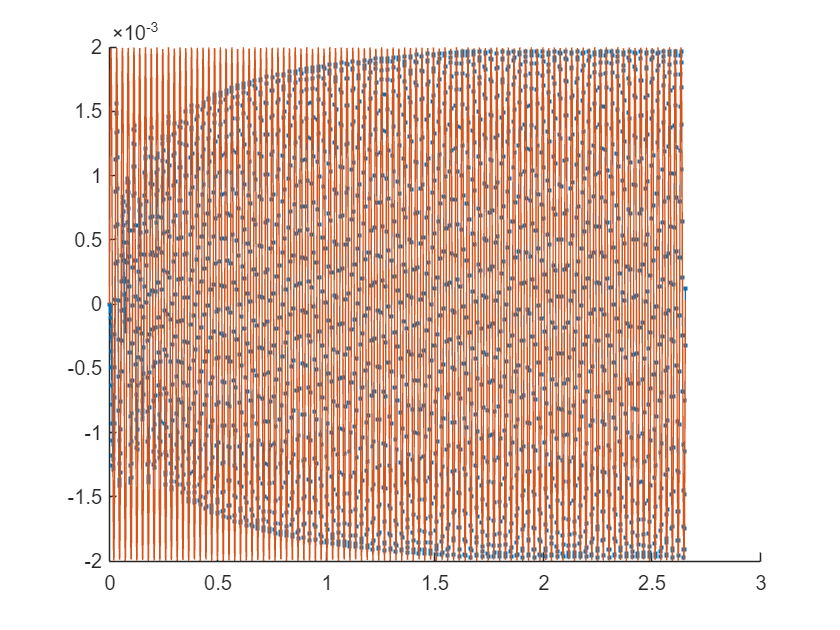

figure;
hold on;

plot(t_all, x_all(:, 1), ".-")
plot(t_all, model.eta_star(t_all))

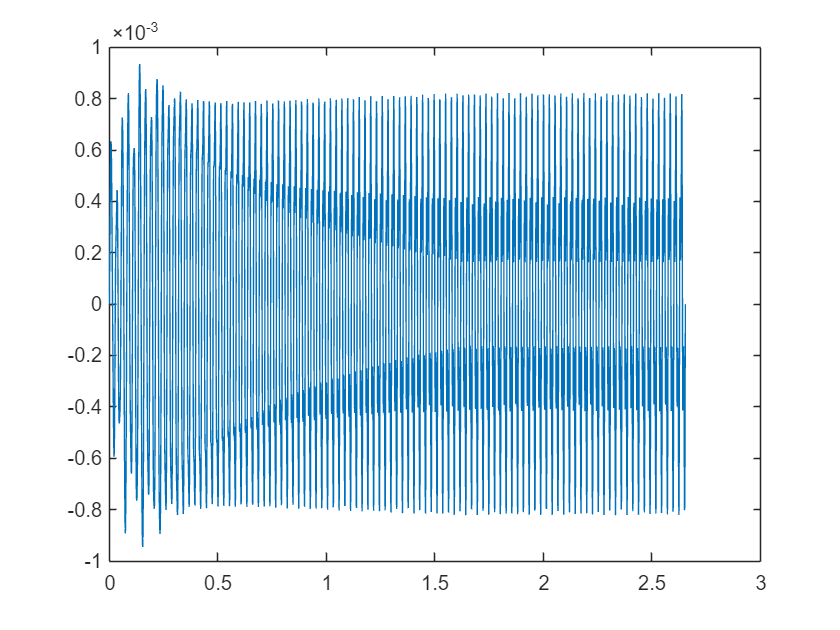

figure
plot(t_all, v_all./10000)

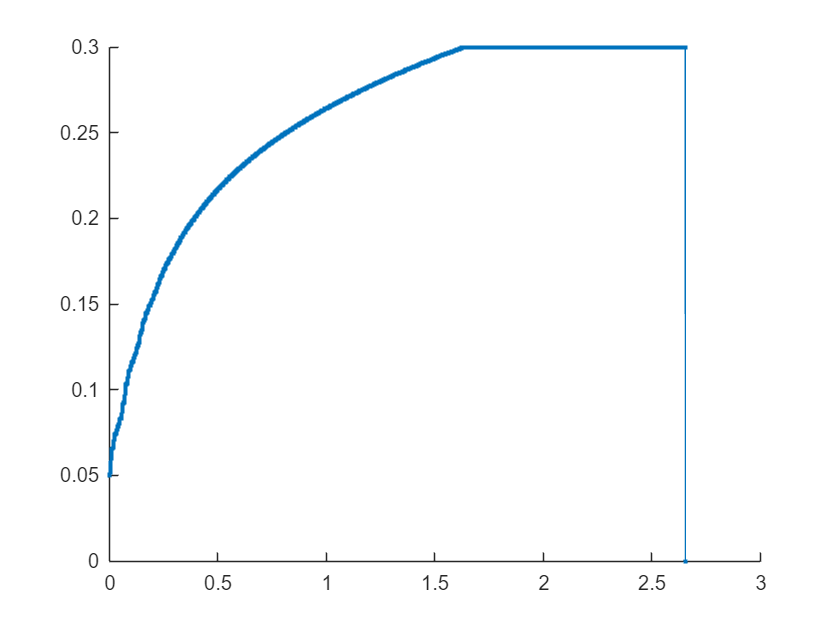


figure;
hold on;
plot(t_all, a_all(:,1), ".-")